# Post-processing

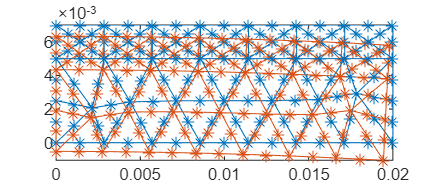

% Surface 8 9 y and z
ElementsOnSurf = [ElementsInDomain(MeshFile, order, 2, 8);
    ElementsInDomain(MeshFile, order, 2, 9)];
Nnodes = size(ElementsOnSurf,1);
factor = 10;
figure
set(gcf,'unit','centimeters','position',[0,0,40,17])
for i = 1:Nnodes
    sequence = ElementsOnSurf(i,:);
    sequence = sequence([1,4,2,5,3,6,1]);
    y = Nodes(sequence,2);
    z = Nodes(sequence,3);
    y_v = y + factor*U(sequence*3-1);
    z_w = z + factor*U(sequence*3);
    plot(y,z,'*-','Color','#0072BD')
    hold on
    plot(y_v,z_w,'*-','Color','#D95319')
end

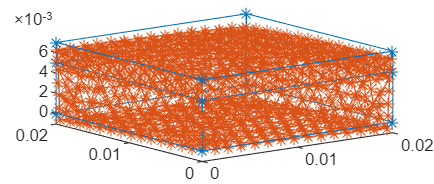

% 3_D
ElementsOnSurf = [ElementsInDomain(MeshFile, order, 2, 1);
    ElementsInDomain(MeshFile, order, 2, 3);
    ElementsInDomain(MeshFile, order, 2, 4);
    ElementsInDomain(MeshFile, order, 2, 5);
    ElementsInDomain(MeshFile, order, 2, 6);
    ElementsInDomain(MeshFile, order, 2, 7);
    ElementsInDomain(MeshFile, order, 2, 8);
    ElementsInDomain(MeshFile, order, 2, 9);
    ElementsInDomain(MeshFile, order, 2, 10);
    ElementsInDomain(MeshFile, order, 2, 11)];
Nnodes = size(ElementsOnSurf,1);
factor = 10;
figure
set(gcf,'unit','centimeters','position',[0,0,40,17])
for i = 1:Nnodes
    sequence = ElementsOnSurf(i,:);
    sequence = sequence([1,4,2,5,3,6,1]);
    x = Nodes(sequence,1);
    y = Nodes(sequence,2);
    z = Nodes(sequence,3);
    x_v = x + factor*U(sequence*3-2);
    y_v = y + factor*U(sequence*3-1);
    z_w = z + factor*U(sequence*3);
%     plot3(x,y,z,'*-','Color','#0072BD')
%     hold on
    plot3(x_v,y_v,z_w,'*-','Color','#D95319')
    hold on
end
a = 0.02;
h1 = 0.005;
h2 = 0.007;
coordinates = [0,0,0;a,0,0;a,a,0;0,a,0;
    0,0,h1;a,0,h1;a,a,h1;0,a,h1;
    0,0,h2;a,0,h2;a,a,h2;0,a,h2;];
coordinates1 = [coordinates(1:4,:);
    coordinates(1,:);
    coordinates(5:8,:);
    coordinates(5,:);
    coordinates(9:12,:);
    coordinates(9,:)];
plot3(coordinates1(:,1),coordinates1(:,2),...
    coordinates1(:,3),'*-','Color','#0072BD')
coordinates1 = [coordinates(2,:);coordinates(6,:);coordinates(10,:)];
plot3(coordinates1(:,1),coordinates1(:,2),...
    coordinates1(:,3),'*-','Color','#0072BD')
coordinates1 = [coordinates(3,:);coordinates(7,:);coordinates(11,:)];
plot3(coordinates1(:,1),coordinates1(:,2),...
    coordinates1(:,3),'*-','Color','#0072BD')
coordinates1 = [coordinates(4,:);coordinates(8,:);coordinates(12,:)];
plot3(coordinates1(:,1),coordinates1(:,2),...
    coordinates1(:,3),'*-','Color','#0072BD')